clc; clear all; close all;
load example.mat;

## Vector creation

xpos = reshape(data.signals.values(1,1,:),[1,5216]);
ypos = reshape(data.signals.values(1,2,:),[1,5216]);
orientations = reshape(data.signals.values(1,3,:),[1,5216]);

## Comet Plot

Carino perchè lascia la scia dietro della traiettoria percorsa, però non si può cambiare il pallino con un triangolo e farlo orientato

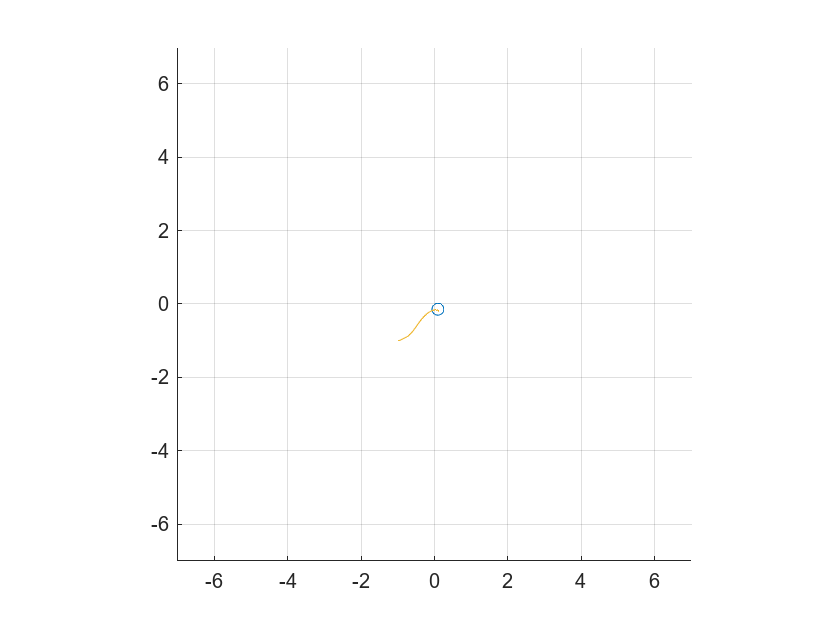

figure

comet(xpos, ypos);
axis square
xlim([-7.0 7.0])
ylim([-7.0 7.0])
grid on

## Ugly version

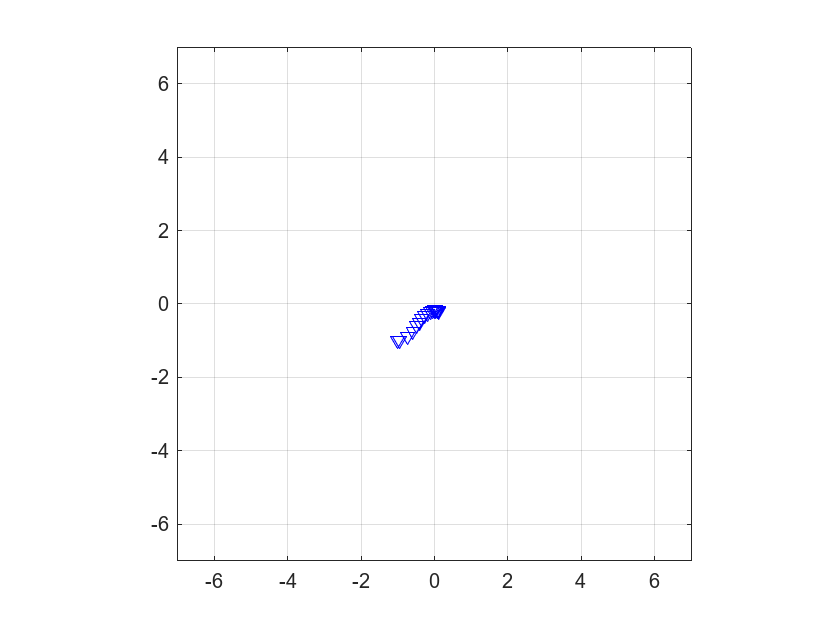

figure

for i = 1:50  %length(xpos)
    plot(xpos(i), ypos(i), 'vb'), hold all
    drawnow
    axis square
    xlim([-7,7]);
    ylim([-7,7]);
end
grid on

## Best version

Triangolino orientato per ogni posizione, volendo si possono tenere tutti in sequenza come nella sezione prima

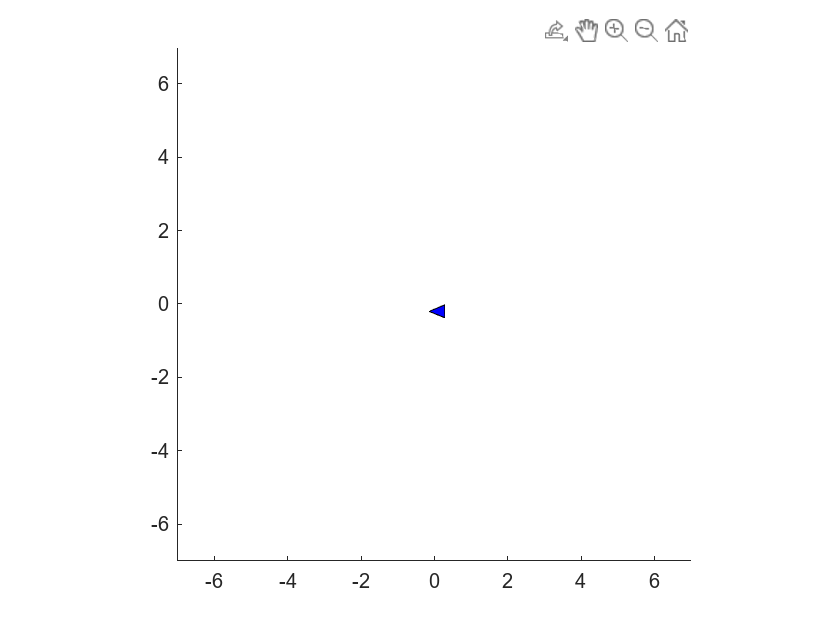

a = [-0.3536 -0.3536]';
b = [.5 0]';
c = [-0.3536 0.3536]';
P = 0.5*[a b c];
p = [];

figure

for i = 1:50%:length(xpos)
    delete(p)
    x = xpos(i);
    y = ypos(i);
    theta = orientations(i);
    R = [ cos(theta) -sin(theta); sin(theta) cos(theta)];
    Prot = R*P;
    Prot_trasl = Prot + [ones(1,3)*x; ones(1,3)*y];
    p = patch(Prot_trasl(1,:),Prot_trasl(2,:),'b');
   
axis square
xlim([-7.0 7.0])
ylim([-7.0 7.0])
    drawnow
    
end